# **Matlab案例代码解析**

## 5. 智能优化算法案例

### 5.8 鲸鱼（WOA）

#### 5.8.1 WOA求解函数极值

算法下载：[https://au.mathworks.com/matlabcentral/fileexchange/55667-the-whale-optimization-algorithm](https://au.mathworks.com/matlabcentral/fileexchange/55667-the-whale-optimization-algorithm)

clear;clc;
% 鲸鱼数量
SearchAgents_no = 30;
% 最大迭代次数
Max_iter = 200;
% 变量维度
dim = 2;
% 上限
ub = 10 * ones(1, dim);
% 下限
lb = -10 * ones(1, dim);
%%%%% 初始化
Leader_pos = zeros(1, dim);
Leader_score = inf;
% 初始化位置
Positions = rand(SearchAgents_no, dim) .* repmat(ub - lb, SearchAgents_no, 1) + repmat(lb, SearchAgents_no, 1); 
Convergence_curve = zeros(1, Max_iter);
% 主循环
for t = 1:Max_iter
    for i = 1:SearchAgents_no
        % 边界处理：越界赋值为边界值
        Flag4ub = Positions(i, :) > ub;
        Flag4lb = Positions(i, :) < lb;
        Positions(i, :) = (Positions(i, :).*(~(Flag4ub + Flag4lb))) + ub.*Flag4ub + lb.*Flag4lb;
        % 计算目标函数
        fitness = ObjFun(Positions(i, :));
        % 更新领头位置
        if fitness < Leader_score
            Leader_score = fitness;
            Leader_pos = Positions(i, :);
        end
    end
    % 线性递减
    a = 2 - t * 2 / Max_iter;
    a2 = -1 - t / Max_iter;   
    % 更新位置
    for i = 1 : SearchAgents_no
        r1 = rand();
        r2 = rand();
        A = 2*a*r1 - a;
        C = 2*r2;
        b = 1;
        l = (a2-1)*rand+1;
        p = rand();
        for j = 1 : dim 
            if p < 0.5   
                if abs(A) >= 1
                    rand_leader_index = floor(SearchAgents_no*rand() + 1);
                    X_rand = Positions(rand_leader_index, :);
                    D_X_rand = abs(C*X_rand(j) - Positions(i, j));
                    Positions(i, j) = X_rand(j) - A*D_X_rand;
                    
                elseif abs(A) < 1
                    D_Leader = abs(C*Leader_pos(j) - Positions(i, j));
                    Positions(i, j) = Leader_pos(j) - A*D_Leader;
                end
            else
                distance2Leader = abs(Leader_pos(j) - Positions(i, j));
                Positions(i, j) = distance2Leader*exp(b.*l).*cos(l.*2*pi) + Leader_pos(j);
            end
        end
    end
    Convergence_curve(t) = Leader_score;
end
disp(['最优值：' num2str(Leader_pos)]);

最优值：-2.6516e-11  3.9705e-09


disp(['最优值对应目标函数：' num2str(Leader_score)]);

最优值对应目标函数：0


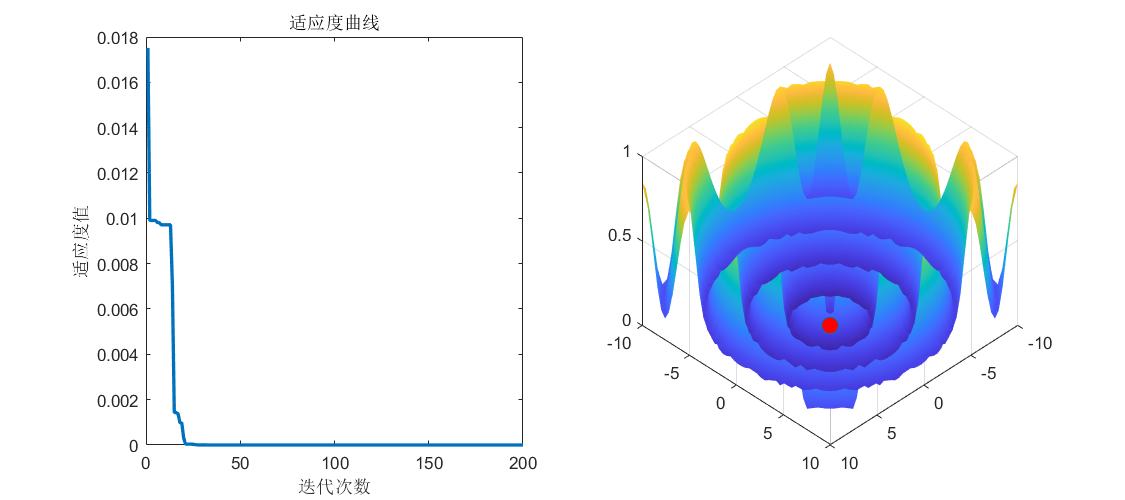

subplot(1, 2, 1)
plot(Convergence_curve, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度曲线');
len = 50;
xRange = linspace(lb(1), ub(1), len);
yRange = linspace(lb(2), ub(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(Leader_pos(1), Leader_pos(2), Leader_score, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end